## Introduction to working with the xATLy toolbox

The xATLy toolkit comprises of various functions and classes that are designed to seamlessly integrate with the MATLAB® environments provided by MathWorks. Its main purpose is to simplify the reading, visualization, and manipulation of ICESat-2 ATL03 and ATL08 data in HDF5 format. Ultimately, the goal of the toolkit is to enable the creation of custom terrain and canopy height datasets that align with specific user requirements.

The xATLy toolkit was created to establish a connection between ATL03 and ATL08 data, with the aim of deriving precise vegetation height estimates. To achieve this, the toolkit has implemented an object-oriented design that consists of three main class objects: Atl03, Atl08, and gtrack.

- The Atl03 class is responsible for providing an interface to access the photon level 3D data stored in HDF5 files, making it easier for users to access this information. The Atl08 class, on the other hand, offers access to a diverse range of ATL08 segment level attributes, such as canopy and terrain height metrics and signal photon level classifications, which can be used to generate highly detailed datasets.

- Finally, the gtrack class is a ground track object that represents one of the six ground tracks present in an ATL03/ATL08 granule. This class plays a crucial role in the process of deriving vegetation height estimates, as it enables users to identify and analyze specific ground tracks that are relevant to their research.

To establish a clear relationship between the gtrack object and matching ATL03 and ATL08 granule objects, the former has been modeled as a OOP composition. This approach ensures that the gtrack object is tightly bound to its corresponding granule objects, allowing for efficient data manipulation.

The methods associated with the gtrack object typically produce tabular data formats that include raw, classified, and normalized ATL03 points. In addition to these outputs, the gtrack object also provides auxiliary data such as ATL08 segment polygons in shapefile or KML format. This makes it easier for users to visualize and analyze the data, as it can be easily integrated into other tools and software.

The following sections demonstrates features of the xATLy toolbox including:

- Defining Atl03 and Atl08 objects

- Defining ground track object for data access

- Exploring and reading data and attributes from defined ground track

- Displaying raw and classified ATL03 point clouds for a ground track

- Generating auxiliary Reference ground track (RGT) and ATL08 segment vector data

- Saving retrieved point cloud data

- Concluding remarks

### Define Atl03 and Atl08 objects

Access to ATL03 and ATL08 data is established through respective `Atl03` and `Atl08` objects as illustrated below. Two file paths are provided, one for the ATL03 and other for the matching ATL08 data.

atl03path = '.\data\ATL03_20190603025340_10050314_002_01.h5'; % ATL03 filepath
atl08path = '.\data\ATL08_20190603025340_10050314_002_01.h5'; % ATL08 filepath


% creates Atl03 and Atl08 objects
a3 = Atl03(atl03path);
a8 = Atl08(atl08path);

Display basic object properties using MATLAB disp function. 

% ATL03 - basic attributes
disp(a3) 

  Atl03 with properties:

        filepath: '.\data\ATL03_20190603025340_10050314_002_01.h5'
     producttype: 'ATL03'
        orbitnum: 3980
        cyclenum: 3
       sc_orient: 0
    groundtracks: {'gt1l'  'gt1r'  'gt2l'  'gt2r'  'gt3l'  'gt3r'}
    beamsequence: {'Strong'  'Weak'  'Strong'  'Weak'  'Strong'  'Weak'}



For a slightly detailed display of granule properties one can use the `showinfo` method for both the `Atl03` and `Atl08` objects. The ATL03/ and ATL08 products have numerous attributes. The `showinfo` method only outputs a few attributes necessary to provide an adequate overview of dataset as shown below.

a3.showinfo() % detailed attributes/values

 <--------------------------- Dataset Info ------------------------->
                                                         
   Granule ID: ATL03_20190603025340_10050314_002_01.h5
   Version ID: 002
   Orbit/Cycle number: 3980/3
   Spacecraft orientation: 0 [Backward] 
                                                         
   Track IDs: | gt1l | gt1r | gt2l | gt2r | gt3l | gt3r | 
   Beam sequence: | Strong | Weak | Strong | Weak | Strong | Weak | 
   Number points: | 77918 | 18455 | 57574 | 20583 | 85455 | 19403 | 
                                                         
   Min/Max Lat/Lon: [-13.7157 23.8022] [-13.7155 23.8626]
   Approx. Range(km): 3.25
                                                         
 <--------------------------- End of Info ------------------------->


% ATL08
disp(a8)

  Atl08 with properties:

        filepath: '.\data\ATL08_20190603025340_10050314_002_01.h5'
     producttype: 'ATL08'
        orbitnum: 3980
        cyclenum: 3
       sc_orient: 0
    groundtracks: {'gt1l'  'gt1r'  'gt2l'  'gt2r'  'gt3l'  'gt3r'}
    beamsequence: {'Strong'  'Weak'  'Strong'  'Weak'  'Strong'  'Weak'}



a8.showinfo()

 <--------------------------- Dataset Info ------------------------->
                                                         
   Granule ID: ATL08_20190603025340_10050314_002_01.h5
   Version ID: 002
   Orbit/Cycle number: 3980/3
   Spacecraft orientation: 0 [Backward] 
                                                         
   Track IDs: | gt1l | gt1r | gt2l | gt2r | gt3l | gt3r | 
   Beam sequence: | Strong | Weak | Strong | Weak | Strong | Weak | 
   No. segments: | 986 | 449 | 985 | 304 | 986 | 320 | 
   No. canopy pts: | 41884 | 4201 | 41601 | 4741 | 47070 | 3705 | 
   No. top.canopy pts: | 13108 | 646 | 13349 | 879 | 15155 | 581 | 
   No. terrain pts: | 153367 | 22768 | 94378 | 14249 | 140335 | 16016 | 
                                                         
   Min/max Lat/Lon: [-13.9793, 23.8290] [-13.9768, 23.8893]
   Approx. distance: 3.51 km
   Min/max canopy height (m): [0.5, 38.2]
   Min/max terrain height (m): [1031.9, 1155.8]
                                        

It is important to note that the orbit number (orbitnum) and cycle number (cyclenum) must match between the two objects in order to ensure that both datasets represent identical ground tracks. This is a critical requirement that must be met to avoid any discrepancies in the data.

As a result of this matching process, the ground tracks (groundtracks) and beam sequence (beamsequence) will also be identical. However, there are instances where some tracks may not be processed in the ATL08 product due to data corruption, resulting in a lack of corresponding ATL08 tracks for some ATL03 tracks.

The spacecraft is responsible for determining the sequence of strong and weak beams, with strong beams leading weak beams in each pair. In this particular case, the spacecraft orientation is backward (sc_orient = 0).

### Define a gtrack object

In the xATLy toolbox, calculations are performed at ground track level. As noted already, a gtrack object has a relationship to matching Atl03 and Atl08 objects to build synergy between the two products for vegetation applications. The code below initializes a gtrack object for the 'gt1l' track, which is a strong beam as shown by the beamlevel attribute below. 

gt = gtrack('gt1l',a3,a8);
disp(gt)

  gtrack with properties:

     gtrackid: 'gt1l'
        atl03: [1×1 Atl03]
        atl08: [1×1 Atl08]
    beamlevel: 'Strong'



From the output, you can see that this ground track object has atl03 and atl08 properties, which establishes the relationship. With the arrangement, one can access ATL03 related attributes through the atl03 object. Likewise, one can access ATL08 attributes through the atl08 object. This facility is demonstrated in the next section.

### Accessing ground track photon or segment level data

*Reading raw point cloud data.* After creating a ground track object, it is possible to read raw ATL03 point cloud data by utilizing the getrawpc method, as demonstrated below. This method returns a table object that contains geolocation, elevation, and signal confidence attributes. Additionally, the table includes estimated along-track distances, which can be used for plotting and distance-based analyses. The along-track distance is calculated by scaling delta times values by a factor of 1 second equals 7000 meters. The table also includes a signal confidence attribute related to land/vegetation surfaces. Please refer to the [ATL03 ATBD](https://nsidc.org/sites/default/files/icesat2_atl03_atbd_r005_0.pdf) for definitions for the other attributes in the table. 

format('bank') % for presentation purposes only - values formatted with 2 decimal places
rpc = gt.getrawpc(); % gets the raw point cloud
% display table columns
disp(rpc.Properties.VariableNames')

    {'segment_id'         }
    {'photon_index'       }
    {'alongtrack_distance'}
    {'deltatime'          }
    {'longitude'          }
    {'latitude'           }
    {'elevation'          }
    {'signal_conf'        }



% disp first five rows and first seven columns of the data - signal_conf
% not dispalyed due to page limitations. You may display the whole table
% using disp(rpc(1:5,:)) 
disp(rpc(1:5,1:7)) 

    segment_id    photon_index    alongtrack_distance     deltatime     longitude    latitude    elevation
    __________    ____________    ___________________    ___________    _________    ________    _________

    1931087.00        1.00               0.00            44765828.48      23.80       -13.72      1099.76 
    1931087.00        2.00               0.00            44765828.48      23.80       -13.72      1085.91 
    1931087.00        3.00               0.70            44765828.48      23.80       -13.72      1089.96 
    1931087.00        4.00               0.70            44765828.48      23.80       -13.72      1086.13 
    1931087.00        5.00               1.40            44765828.48      23.80       -13.72      1102.05 



*Retrieving classified ATL03 point clouds. *The xATLy toolbox facilitates linking of ATL08 signal photon classifications, under the signal_photons group, with raw ATL03 point clouds to derive a classified point cloud through the `getclassedpc` method. 

cpc = gt.getclassedpc(); % get classed point cloud
% display table columns
disp(cpc.Properties.VariableNames')

    {'segment_id'         }
    {'photon_index'       }
    {'alongtrack_distance'}
    {'deltatime'          }
    {'longitude'          }
    {'latitude'           }
    {'elevation'          }
    {'signal_conf'        }
    {'classed_pc_flag'    }



Notice that the table columns above are identical to columns in rpc except for an additional class_pc_flag attribute, which holds the ATL08 photon class values. 

% disp first five rows and selected columns of the data
selcols = [1,3,5:9]; % selected column indices
disp(cpc(1:5,selcols))

    segment_id    alongtrack_distance    longitude    latitude    elevation    signal_conf    classed_pc_flag
    __________    ___________________    _________    ________    _________    ___________    _______________

    1931087.00           0.00              23.80       -13.72      1099.76        4.00             2.00      
    1931087.00           0.00              23.80       -13.72      1085.91        4.00             1.00      
    1931087.00           0.70              23.80       -13.72      1089.96        4.00             2.00      
    1931087.00           0.70              23.80       -13.72      1086.13        4.00             1.00      
    1931087.00           1.40              23.80       -13.72      1102.05        4.00             3.

*Retrieving normalized point cloud: *The xATLy toolbox provides a means of retrieving a classified point cloud normalized to aboveground elevation level, which is useful in estimating vegetation canopy heights. This normalized point cloud can be obtained using two methods:

- The `getnormalizedpc` method can be applied directly to the ground track object, retrieving the classified point cloud and then normalizing it to aboveground level.

- Alternatively, the normalized point cloud can be obtained from a table object returned by the `getclassedpc` method, which applies normalization to the table object.

If the classified point cloud has already been retrieved, the second method is more efficient. In either case, the resulting table will include an nelevation column defining the aboveground heights.

% first approach
npc = gt.getnormalizedpc(); % using default parameter values

% display table columns
disp(npc.Properties.VariableNames')

    {'segment_id'         }
    {'photon_index'       }
    {'alongtrack_distance'}
    {'deltatime'          }
    {'longitude'          }
    {'latitude'           }
    {'elevation'          }
    {'signal_conf'        }
    {'classed_pc_flag'    }
    {'nelevation'         }



selcols = [1,3,5:7,9:10]; % selected column indices
disp(npc(1:5,selcols)) % some columns intentionally left out due to page limits

    segment_id    alongtrack_distance    longitude    latitude    elevation    classed_pc_flag    nelevation
    __________    ___________________    _________    ________    _________    _______________    __________

    1931087.00           0.00              23.80       -13.72      1099.76          2.00            13.49   
    1931087.00           0.70              23.80       -13.72      1089.96          2.00             3.71   
    1931087.00           1.40              23.80       -13.72      1102.05          3.00            15.81   
    1931087.00           1.40              23.80       -13.72      1086.38          1.00             0.14   
    1931087.00           2.80              23.80       -13.72      1086.36          1.00             0.14  

% second approach
[grndFunc, ~] = fitgroundmodel(cpc); % fit curve to terrain points to estimate ground level
removeptsbelow = true; % remove points below fitted ground level
npc = normalizepts(cpc,grndFunc,removeptsbelow); % using default parameter values
disp(npc(1:5,selcols))

    segment_id    alongtrack_distance    longitude    latitude    elevation    classed_pc_flag    nelevation
    __________    ___________________    _________    ________    _________    _______________    __________

    1931087.00           0.00              23.80       -13.72      1099.76          2.00            13.49   
    1931087.00           0.70              23.80       -13.72      1089.96          2.00             3.71   
    1931087.00           1.40              23.80       -13.72      1102.05          3.00            15.81   
    1931087.00           1.40              23.80       -13.72      1086.38          1.00             0.14   
    1931087.00           2.80              23.80       -13.72      1086.36          1.00             0.14  

*Reading ATL08 data.* The ground track object's `getATL08data` method allows for reading data from an ATL08 granule. ATL08 data are grouped into two main categories: *'signal_photons'* and* 'land_segments'*. The former pertains to parameters related to individual photons, while the latter pertains to segment-level metrics.

Within the land_segments category, there are two subgroups: *'canopy' *and *'terrain'*, which contain metrics related to canopy and terrain heights. The `getATL08data` method enables retrieval of segment-level, canopy, and terrain data. By default, the method retrieves longitude, latitude, number of points in segment (*n_seg_ph*), canopy height (*h_canopy*), and mean terrain height (h_te_mean). The resulting output also includes the ATL08 *segment_id_beg* attribute as a unique identifier.

% read ATL08 data using default parameter values
attr_tbl = gt.getATL08data();
disp(attr_tbl(1:5,:)) % display first 5 rows

    segment_id_beg    longitude    latitude    n_seg_ph    h_canopy    h_te_mean
    ______________    _________    ________    ________    ________    _________

      1929624.00        23.83       -13.98      176.00        NaN       1047.82 
      1929629.00        23.83       -13.98      199.00        NaN       1047.76 
      1929634.00        23.83       -13.98      202.00       8.34       1047.12 
      1929639.00        23.83       -13.98      197.00       4.90       1047.53 
      1929644.00        23.83       -13.98      232.00       4.27       1046.46 



% read ATL08 data by specifying custom list of attributes
landseg_atrr = {'longitude','latitude','night_flag'}; % land_segments attributes
ca_attr = {'n_ca_photons','n_toc_photons','h_canopy'}; % canopy group attributes
te_attr = {}; % gets no attributes from terrain group
attr_tbl = gt.getATL08data(landseg_atrr,ca_attr,te_attr);
disp(attr_tbl(1:5,:)) % display first 5 rows

    segment_id_beg    longitude    latitude    night_flag    n_ca_photons    n_toc_photons    h_canopy
    ______________    _________    ________    __________    ____________    _____________    ________

      1929624.00        23.83       -13.98        1.00          47.00             0.00           NaN  
      1929629.00        23.83       -13.98        1.00          43.00             0.00           NaN  
      1929634.00        23.83       -13.98        1.00          38.00            23.00          8.34  
      1929639.00        23.83       -13.98        1.00          42.00            17.00          4.90  
      1929644.00        23.83       -13.98        1.00          45.00            17.00          4.27  



To successfully retrieve ATL08 data, one must provide exact attribute names from the ATL08 data dictionary. The xATLy toolbox includes a `showattr` method that allows for listing the attributes in a given group. The method displays the attributes in rows, with each row containing 5 attribute names separated by the "|" character. An example of the `showattr` method's output is shown below.

% List segment level attributes
gt.showattr('land_seg') % lists segment level attributes

------------------------------- land_seg group attributes -------------------------------
[1-5] | asr | atlas_pa | beam_azimuth | beam_coelev | brightness_flag
[6-9] | cloud_flag_atm | cloud_fold_flag | delta_time | delta_time_beg
[10-13] | delta_time_end | dem_flag | dem_h | dem_removal_flag
[14-17] | h_dif_ref | last_seg_extend | latitude | layer_flag
[18-21] | longitude | msw_flag | n_seg_ph | night_flag
[22-25] | ph_ndx_beg | ph_removal_flag | psf_flag | rgt
[26-29] | segment_id_beg | segment_id_end | segment_landcover | segment_snowcover
[30-33] | segment_watermask | sigma_across | sigma_along | sigma_atlas_land
[34-37] | sigma_h | sigma_topo | snr | solar_azimuth
[38-41] | solar_elevation | surf_type | terrain_flg | urban_flag
*** Check the ATL08 ATBD for attribute descriptions ***
-----------------------------------------------------------------------------------------


% list canopy related height metrics
gt.showattr('canopy') % lists canopy metrics

------------------------------- canopy group attributes -------------------------------
[1-5] | canopy_flag | canopy_h_metrics | canopy_h_metrics_abs | canopy_openness | canopy_rh_conf
[6-9] | centroid_height | h_canopy | h_canopy_abs | h_canopy_quad
[10-13] | h_canopy_uncertainty | h_dif_canopy | h_max_canopy | h_max_canopy_abs
[14-17] | h_mean_canopy | h_mean_canopy_abs | h_median_canopy | h_median_canopy_abs
[18-21] | h_min_canopy | h_min_canopy_abs | landsat_flag | landsat_perc
[22-24] | n_ca_photons | n_toc_photons | toc_roughness
*** Check the ATL08 ATBD for attribute descriptions ***
---------------------------------------------------------------------------------------


% list terrain related height metrics
gt.showattr('terrain') % lists terrain metrics

------------------------------- terrain group attributes -------------------------------
[1-5] | h_te_best_fit | h_te_interp | h_te_max | h_te_mean | h_te_median
[6-9] | h_te_min | h_te_mode | h_te_skew | h_te_std
[10-12] | h_te_uncertainty | n_te_photons | terrain_slope
*** Check the ATL08 ATBD for attribute descriptions ***
----------------------------------------------------------------------------------------


## Visualizing photon data

The `atdplot `utility function allows for visualization of ground track point cloud data by plotting the along-track distance against elevation or aboveground height. The function can be called using either the ground track object or the table objects returned by the `getrawpc`, `getclassedpc`, and `getnormalizedpc` methods. It should be noted that plotting directly from the ground track object retrieves data on the fly and may be slower than using pre-retrieved table objects.

The following example demonstrates the visualization of raw, classified, and normalized point clouds in a tiled layout. All graphs are focused on data stretching from 300 m to 800 m along-track.

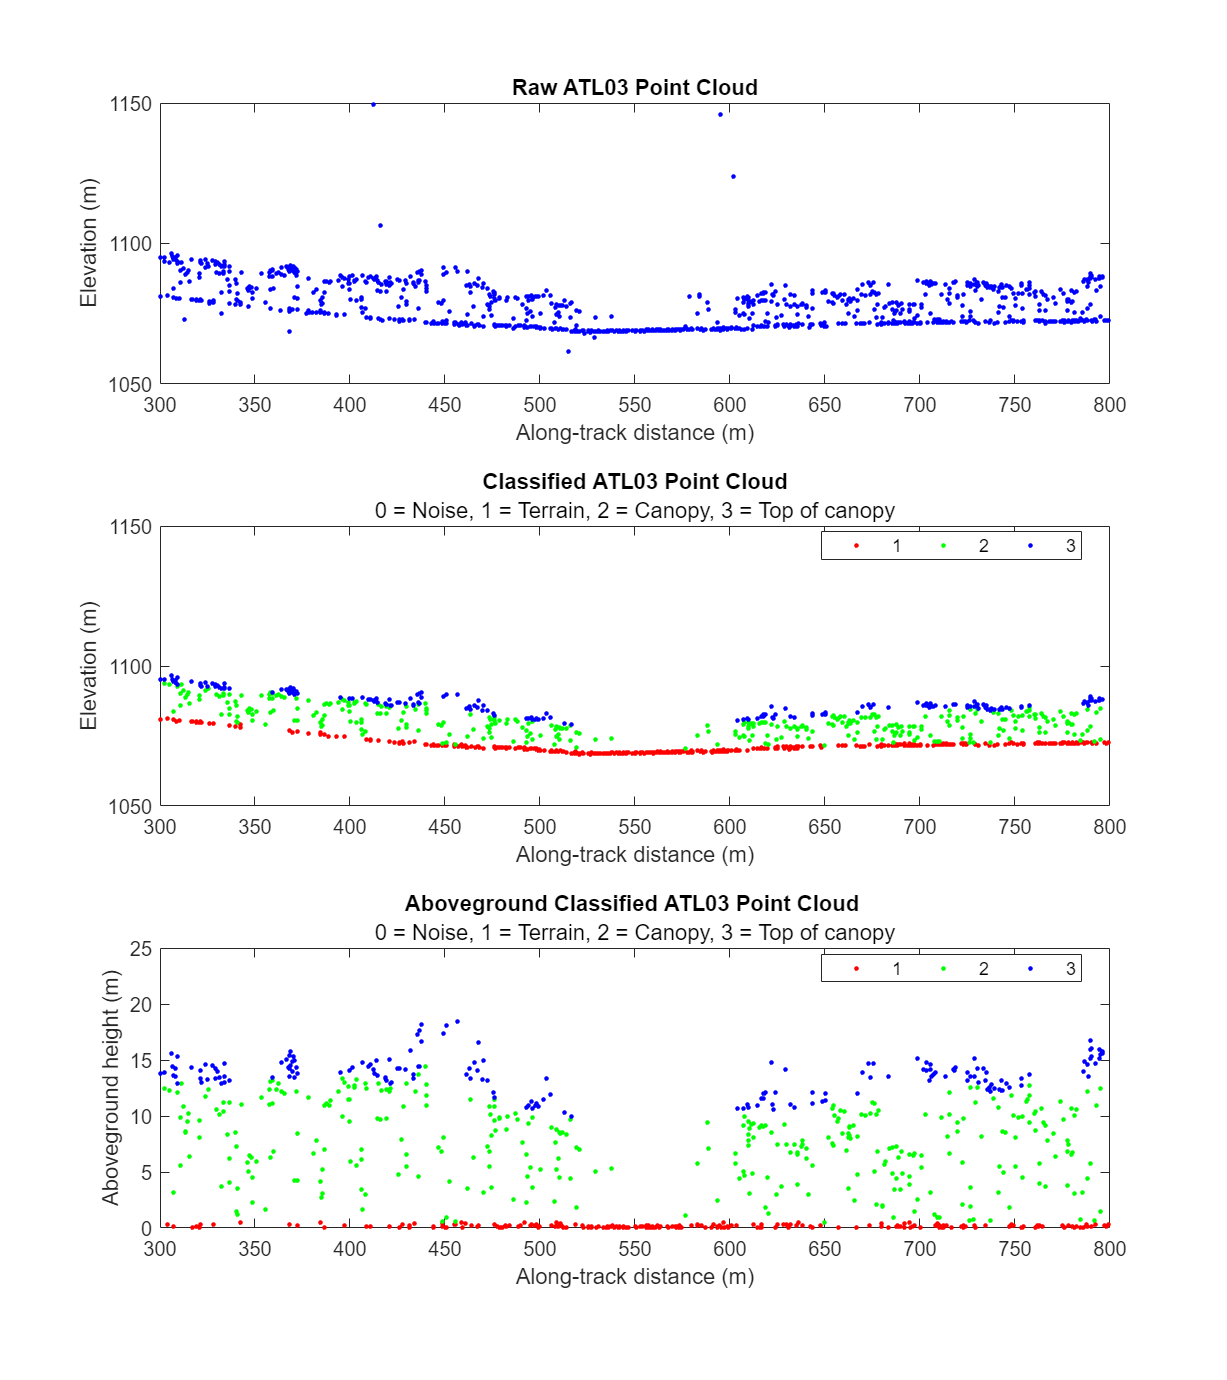

atdlim = [300,800]; % restricts plotting to this atd range

figure('units','normalized','outerposition',[0.0 0.0 0.5 1]);
tiledlayout(3,1);

% plot raw point cloud directly from gt object
ax0 = nexttile;
atdplot(gt,'r',[],atdlim) % plot using default colors
box on
xlim([atdlim(1),atdlim(2)])
ylim([1050,1150])

% plot classified point cloud 
ax1 = nexttile;
atdplot(cpc,'c',[],atdlim)
box on
xlim([atdlim(1),atdlim(2)])
ylim([1050,1150])

% plot aboveground point cloud
ax2 = nexttile;
atdplot(npc,'n',[],atdlim)
box on
xlim([atdlim(1),atdlim(2)])
ylim([0,25])
linkaxes([ax0,ax1, ax2],'x')

### Saving attribute data

Attribute data, e.g. raw point clouds, can readily be saved as ASCII text files to facilitate further analyses. The code below saves the *cpc* table retrieved in the preceding steps to a CSV file using the `savetable` function

pc_fn = './temp/gt1l_tbl.csv';
savetable(cpc,pc_fn) % writes the classified pc

### Writing auxilliary vector data

Auxiliary outputs such as KML or Shapefiles representing a reference ground track (rgt) or segment level polygons can be readily generated to support visualization, presentation, or validation assessments. The current implementation only supports saving outputs in WGS84 geographical coordinates.

rgt_fn = './temp/gt1l_rgt.shp'; % output filepath
gt.writergt(rgt_fn) % writes the rgt as shapefile

seg_fn = './temp/gt1l_seg.shp';
gt.writesegpol(seg_fn) % writes the ATL08 segment polygons as shapefile

## Concluding remarks

This notebook showcased the utilization of the xATLy toolbox for land and vegetation applications, specifically for reading, visualization, and exporting data from both ATL03 and ATL08 datasets. The majority of the functions utilized in this demonstration were executed with default parameter settings. It is recommended to refer to the documentation of each method to explore further possibilities for utilizing the toolbox to fulfill your specific needs.